
$$\textbf{Q3.  PCA and Hyperplane Fitting}$$


• (5 points) Repeat the same analysis for the set of points in "points2D_Set2.mat". Show a scatter plot of the points. Overlay on the scatter plot, the graph of a line showing the linear relationship between Y and X.

Direction of maximal variance passes through mean, So we first calculate mean of given data.


$$$$\mu_x = \frac{\sum x_i}{N}$$
$$\mu_y = \frac{\sum y_i}{N}$$$$


load('../../data/points2D_Set2.mat','y');
load('../../data/points2D_Set2.mat','x');
sz_x = size(x,1);
sz_y = size(y,1);
mean_x = sum(x)./sz_x;
mean_y = sum(y)./sz_y;
x_dist = x - mean_x;
y_dist = y - mean_y;

To calculate covariance matrix we'll find covariance of each pair as:


$$$$Cov_{xx} = \frac{(x - \mu_x)(x - \mu_x)^{T}}{N}$$
$$Cov_{xy} = cov_{yx} = \frac{(x - \mu_x)(y - \mu_y)^{T}}{N}$$
$$Cov_{yy} = \frac{(y - \mu_y)(y - \mu_y)^{T}}{N}$$ $$


So we get the Covariance matrix C as:


$$\left\lbrack \begin{array}{cc}
{\textrm{Cov}}_{\textrm{xx}}  & {\textrm{Cov}}_{\textrm{xy}} \\
{\textrm{Cov}}_{\textrm{yx}}  & {\textrm{Cov}}_{\textrm{yy}} 
\end{array}\right\rbrack$$


cov_xx = (transpose(x_dist)*x_dist)./sz_x;
cov_yy = (transpose(y_dist)*y_dist)./sz_y;
cov_xy = (transpose(y_dist)*x_dist)./sz_x;
cov_mat = [cov_xx , cov_xy ; cov_xy, cov_yy];

Now

using eig() function, we can get two matrices V and D, where D is diagonal matrix having eigenvalues

of covariance matrix as diagonal entries and V will have corresponding eigenvectors as it’s column. we’ll compare

both the diagonal entries and check which is larger (choosing maximum eigenvalue) and then choose corresponding

column of V. Here we got desired eigenvector.

[V,D] = eig(cov_mat);
if(D(1,1) > D(2,2))
    max_eig = 1;
else
    max_eig = 2;
end
eigenvector = V(:,max_eig);

Finally using linspace we’ll generate x values in the range minimum of data to maximum of data and then calculate

corresponding y by equation $$ y - \mu_{y} = \frac{b}{a} (x - \mu_{x})$$ and plot the line on scatter plot.

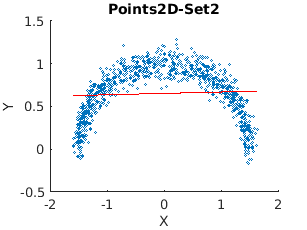

slope = eigenvector(2,1)./eigenvector(1,1);
abscissa = linspace(min(x),max(x),1000);
ordinate = mean_y + slope.*(abscissa - mean_x);
hold on;
scatter(x,y,1);
plot(abscissa,ordinate,'red');
hold off;

title("Points2D-Set2")
xlabel("X")
ylabel("Y")